Section and Code

Section 1: Title and Description

# Introduction to MATLAB with EV Battery Example

Section 2: Basic Variable Assingnment

% Battery cell properties
voltage = 3.9;       % in Volts
current = 2.5;       % in Amps
capacity = 2.5;      % in Ah

Section 3: Calculate Power and Energy

% Power = Voltage * Current
power = voltage * current;

% Energy = Power * time (let’s say 1 hour)
energy = power * 3600;  % in watt-seconds or joules

Section 4: Display Results

disp("Battery Output Power (W):");

Battery Output Power (W):


disp(power);

    9.7500




fprintf("Energy delivered in 1 hour: %.2f Joules\n", energy);

Energy delivered in 1 hour: 35100.00 Joules


Section 5: Basic State of Charge Estimation

% SoC drop during 0.5-hour discharge at 2.5 A
discharge_time = 0.5;  % in hours
soc_drop = (discharge_time * current) / capacity * 100

soc_drop = 50

remaining_soc = 100 - soc_drop;

fprintf("Remaining State of Charge: %.2f\n", remaining_soc);

Remaining State of Charge: 50.00


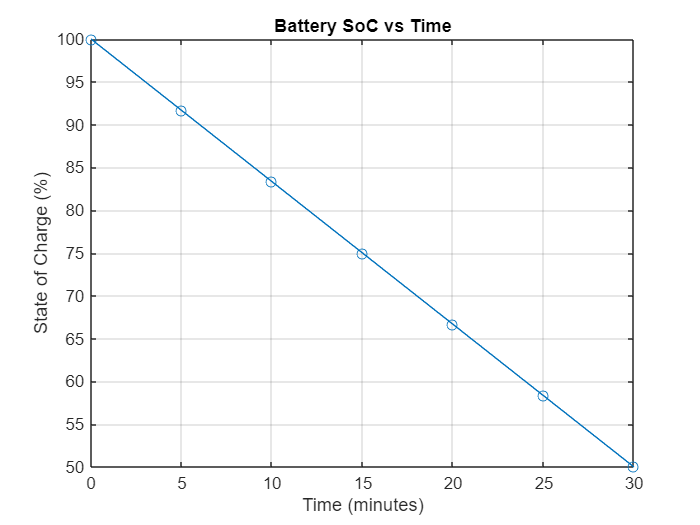

% SoC over 30 minutes (assume linear drop)
time = 0:5:30;  % in minutes
soc = 100 - (time / 60) * (current / capacity * 100);

plot(time, soc, '-o')
xlabel('Time (minutes)')
ylabel('State of Charge (%)')
title('Battery SoC vs Time')
grid on